# Proyecto 3

%% Initialize COBRA Toolbox
initCobraToolbox;



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2022
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.36.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of ibm_cplex, so it cannot be tested
Could not find installation of tomlab_cplex, so it cannot be tested
GLPK Simplex Optimizer, v4.42
1 row, 2 columns, 1 non-zero
Preprocessing...
~     0: obj =   0.000000000e+00  infeas =  0.000e+00
OPTIMAL SOLUTION FOUND BY LP PREPROCESSOR

 > [glpk] Primal optimality condition in solveCobraLP satisfied.Could not find installation of mosek, so it cannot be tested

   --------------------------------------------------------
   pdco.m                      Version pdco5 of 15 Jun 2018
   Primal-dual barrier method to minimize a convex function
   subject to linear constraints Ax + r = b,  bl <= x <= bu
                                                           
   Michael Saunders       SOL and ICME, Stanford University
   Contributors:     Byunggyoo Kim (SOL), Chris Maes (ICME)
                     Santiago

changeCobraSolver: problem initialising CPLEX object: Undefined function 'Cplex' for input arguments of type 'struct'.
Could not find installation of cplexlp, so it cannot be tested
Could not find installation of tomlab_snopt, so it cannot be tested
 Done.
 > Setting default solvers ...Could not find installation of mosek, so it cannot be tested
 Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved as ~/pathdef.m.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP 	   EP
	------------------------------------------------------------------------------
	gurobi       	active        	    0 	    0 	    0 	    0 	    - 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    0 	    - 	    -
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    - 	    -
	mosek        	active        	    0 	    - 	    0 	    - 	    - 	    0
	matlab       	act

%% Load Models
model = readCbModel('../Codes-and-models/iMAC868_GSM.xlsx');

 > Excel is not installed; limit of 10000 reactions.

Adding the following Metabolites to the model:
10fthf[c]
13dpg[c]
1pyr4m5c[c]
1pyr5c[c]
23dhdp[c]
23dhmb[c]
23dhmp[c]
24sf[c]
25aics[c]
25dhpp[c]
25dthpp[c]
26dap-LL[c]
26dap-M[c]
2ahbut[c]
2c25dho[c]
2cpr5p[c]
2dhp[c]
2dr1p[c]
2dr5p[c]
2frald[c]
2h3moa[c]
2ins[c]
2ippm[c]
2mafr[c]
2mahmp[c]
2mbcoa[c]
2mbr[c]
2mop[c]
2obut[c]
2ood[c]
2pg[c]
2pglyc[c]
2plac-L[c]
2ppoh[c]
2saa[c]
2tcc[c]
34hpp[c]
35cgmp[c]
36dahx[c]
3c2hmp[c]
3c3hmp[c]
3c4mop[c]
3dhq[c]
3dhsk[c]
3hcdgggp[c]
3hdgggp[c]
3hdgggps[c]
3hdggpg[c]
3hdggpgp[c]
3hdggpi[c]
3hdpgpe[c]
3hdpgpg[c]
3hdpgpi[c]
3hdpgps[c]
3hfrdp[c]
3hggdp[c]
3hgrdp[c]
3hmp[c]
3ig3p[c]
3mob[c]
3mop[c]
3ophb[c]
3pg[c]
3php[c]
3psme[c]
3spyr[c]
4abut[c]
4abutn[c]
4abz[c]
4abz[e]
4adhq[c]
4adhs[c]
4ahmmp[c]
4ampm[c]
4as[c]
4das[c]
4gaepmamfr[c]
4ggaepmamfr[c]
4gggaepmamfr[c]
4hba[c]
4hbz[c]
4hphac[c]
4hphac[e]
4mhetz[c]
4mop[c]
4mpetz[c]
4pasp[c]
4ppan[c]
4ppcys[c]
4r5au[c]
5aizc[c]
5aop[c]
5aprbu[c]
5c5

model_native = readCbModel('../Codes-and-models/iMAC868_GSM_native.xlsx');

 > Excel is not installed; limit of 10000 reactions.

Adding the following Metabolites to the model:
10fthf[c]
13dpg[c]
1pyr4m5c[c]
1pyr5c[c]
23dhdp[c]
23dhmb[c]
23dhmp[c]
24sf[c]
25aics[c]
25dhpp[c]
25dthpp[c]
26dap-LL[c]
26dap-M[c]
2ahbut[c]
2c25dho[c]
2cpr5p[c]
2dhp[c]
2dr1p[c]
2dr5p[c]
2frald[c]
2h3moa[c]
2ins[c]
2ippm[c]
2mafr[c]
2mahmp[c]
2mbcoa[c]
2mbr[c]
2mop[c]
2obut[c]
2ood[c]
2pg[c]
2pglyc[c]
2plac-L[c]
2ppoh[c]
2saa[c]
2tcc[c]
34hpp[c]
35cgmp[c]
36dahx[c]
3c2hmp[c]
3c3hmp[c]
3c4mop[c]
3dhq[c]
3dhsk[c]
3hcdgggp[c]
3hdgggp[c]
3hdgggps[c]
3hdggpg[c]
3hdggpgp[c]
3hdggpi[c]
3hdpgpe[c]
3hdpgpg[c]
3hdpgpi[c]
3hdpgps[c]
3hfrdp[c]
3hggdp[c]
3hgrdp[c]
3hmp[c]
3ig3p[c]
3mob[c]
3mop[c]
3ophb[c]
3pg[c]
3php[c]
3psme[c]
3spyr[c]
4abut[c]
4abutn[c]
4abz[c]
4abz[e]
4adhq[c]
4adhs[c]
4ahmmp[c]
4ampm[c]
4as[c]
4das[c]
4gaepmamfr[c]
4ggaepmamfr[c]
4gggaepmamfr[c]
4hba[c]
4hbz[c]
4hphac[c]
4hphac[e]
4mhetz[c]
4mop[c]
4mpetz[c]
4pasp[c]
4ppan[c]
4ppcys[c]
4r5au[c]
5aizc[c]
5aop[c]
5aprbu[c]
5c5

model_methane = readCbModel('../Codes-and-models/iMAC868_GSM_methane.xlsx');

 > Excel is not installed; limit of 10000 reactions.

Adding the following Metabolites to the model:
10fthf[c]
13dpg[c]
1pyr4m5c[c]
1pyr5c[c]
23dhdp[c]
23dhmb[c]
23dhmp[c]
24sf[c]
25aics[c]
25dhpp[c]
25dthpp[c]
26dap-LL[c]
26dap-M[c]
2ahbut[c]
2c25dho[c]
2cpr5p[c]
2dhp[c]
2dr1p[c]
2dr5p[c]
2frald[c]
2h3moa[c]
2ins[c]
2ippm[c]
2mafr[c]
2mahmp[c]
2mbcoa[c]
2mbr[c]
2mop[c]
2obut[c]
2ood[c]
2pg[c]
2pglyc[c]
2plac-L[c]
2ppoh[c]
2saa[c]
2tcc[c]
34hpp[c]
35cgmp[c]
36dahx[c]
3c2hmp[c]
3c3hmp[c]
3c4mop[c]
3dhq[c]
3dhsk[c]
3hcdgggp[c]
3hdgggp[c]
3hdgggps[c]
3hdggpg[c]
3hdggpgp[c]
3hdggpi[c]
3hdpgpe[c]
3hdpgpg[c]
3hdpgpi[c]
3hdpgps[c]
3hfrdp[c]
3hggdp[c]
3hgrdp[c]
3hmp[c]
3ig3p[c]
3mob[c]
3mop[c]
3ophb[c]
3pg[c]
3php[c]
3psme[c]
3spyr[c]
4abut[c]
4abutn[c]
4abz[c]
4abz[e]
4adhq[c]
4adhs[c]
4ahmmp[c]
4ampm[c]
4as[c]
4das[c]
4gaepmamfr[c]
4ggaepmamfr[c]
4gggaepmamfr[c]
4hba[c]
4hbz[c]
4hphac[c]
4hphac[e]
4mhetz[c]
4mop[c]
4mpetz[c]
4pasp[c]
4ppan[c]
4ppcys[c]
4r5au[c]
5aizc[c]
5aop[c]
5aprbu[c]
5c5

%% Principal Component Analysis
[U,S,V] = svds(model.S)

U =    -0.0000    0.0005    0.0009   -0.0019    0.0034   -0.0025
   -0.0000   -0.0002   -0.0006    0.0029   -0.0080   -0.0060
   -0.0001   -0.0004   -0.0008   -0.0027    0.0010   -0.0011
    0.0001   -0.0026   -0.0022   -0.0006   -0.0077    0.0014
    0.0000   -0.0018   -0.0006    0.0023   -0.0078    0.0022
   -0.0000    0.0023   -0.0021   -0.0028    0.0016   -0.0018
   -0.0000    0.0012   -0.0010   -0.0025    0.0019   -0.0018
   -0.0001   -0.0010   -0.0023   -0.0030   -0.0048   -0.0008
    0.0001   -0.0001   -0.0001    0.0024   -0.0023    0.0017
    0.0001   -0.0020   -0.0012   -0.0050   -0.0021   -0.0029


S =   151.5227         0         0         0         0         0
         0   38.0446         0         0         0         0
         0         0   21.6595         0         0         0
         0         0         0   15.9953         0         0
         0         0         0         0   14.9594         0
         0         0         0         0         0   12.5919


V =     0.0000   -0.0002   -0.0005    0.0046   -0.0056   -0.0265
    0.0089   -0.0300   -0.0336   -0.0119   -0.0240    0.0468
    0.0000   -0.0000   -0.0007   -0.0000   -0.0008   -0.0141
    0.0029    0.0050    0.0065    0.0384   -0.0259   -0.1018
    0.0000   -0.0000   -0.0008    0.0021   -0.0011   -0.0150
   -0.0000   -0.0000   -0.0000    0.0000   -0.0001    0.0015
    0.0059   -0.0124   -0.0123    0.0347   -0.0441   -0.0955
   -0.0002    0.0462   -0.0193   -0.0057    0.0048    0.0296
    0.0030    0.0044    0.0049   -0.0432    0.0388   -0.0242
    0.0089   -0.0088   -0.0119   -0.0003   -0.0132   -0.1392


Vt = V.'

Vt =     0.0000    0.0089    0.0000    0.0029    0.0000   -0.0000    0.0059   -0.0002    0.0030    0.0089   -0.0030    0.0059    0.0059    0.0000    0.0030    0.0090    0.0031    0.0118    0.0030    0.0059    0.0030   -0.0000   -0.0002    0.0030    0.0000    0.0030    0.0058    0.0030   -0.0030    0.0177   -0.0000    0.0000    0.0030    0.0030    0.0029    0.0059    0.0000   -0.0030    0.0060    0.0061    0.0029    0.0091    0.0090    0.0000   -0.0001    0.0030    0.0000    0.0089    0.0090    0.0000
   -0.0002   -0.0300   -0.0000    0.0050   -0.0000   -0.0000   -0.0124    0.0462    0.0044   -0.0088    0.0172   -0.0126    0.0095   -0.0001    0.0049   -0.0336   -0.0416   -0.0030    0.0046    0.0096   -0.0166   -0.0000    0.0463    0.0037   -0.0000   -0.0176    0.0096   -0.0201   -0.0039    0.0044    0.0000   -0.0027    0.0037    0.0044    0.0049   -0.0125    0.0007    0.0173   -0.0374   -0.0588    0.0049   -0.0551   -0.0337   -0.0210    0.0248    0.0039   -0.0004   -0.0090   -0.0309    

%% FBA for Biomass in native substrate and in substrate with Methane
FBA_overall_native = optimizeCbModel(model_native, 'max') 

FBA_overall_native = struct with fields:
    origStatText: []
               f: 0.0925
              f0: NaN
              f1: 0.0925
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0190
           basis: []
          vars_v: []
               x: [845×1 double]


FBA_overall_methane = optimizeCbModel(model_methane, 'max')

FBA_overall_methane = struct with fields:
    origStatText: []
               f: 0.2656
              f0: NaN
              f1: 0.2656
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0156
           basis: []
          vars_v: []
               x: [845×1 double]


%% FBA for Acetate in native substrate and in substrate with Methane
model_native = changeObjective(model_native, 'EX_ac[e]')

model_native = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_native.xlsx'


model_methane = changeObjective(model_methane, 'EX_ac[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


FBA_acetate_native = optimizeCbModel(model_native, 'max') 

FBA_acetate_native = struct with fields:
    origStatText: []
               f: -10
              f0: NaN
              f1: -10
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0121
           basis: []
          vars_v: []
               x: [845×1 double]


FBA_acetate_methane = optimizeCbModel(model_methane, 'max')

FBA_acetate_methane = struct with fields:
    origStatText: []
               f: 5.0000
              f0: NaN
              f1: 5.0000
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0126
           basis: []
          vars_v: []
               x: [845×1 double]


%% FBA for Methanol in native substrate and in substrate with Methane
model_native = changeObjective(model_native, 'EX_meoh[e]')

model_native = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_native.xlsx'


model_methane = changeObjective(model_methane, 'EX_meoh[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


FBA_methanol_native = optimizeCbModel(model_native, 'max') 

FBA_methanol_native = struct with fields:
    origStatText: []
               f: 0
              f0: NaN
              f1: 0
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0120
           basis: []
          vars_v: []
               x: [845×1 double]


FBA_methanol_methane = optimizeCbModel(model_methane, 'max')

FBA_methanol_methane = struct with fields:
    origStatText: []
               f: 10.0000
              f0: NaN
              f1: 10.0000
              f2: NaN
               v: [845×1 double]
               y: [718×1 double]
               w: [845×1 double]
               s: [718×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.0173
           basis: []
          vars_v: []
               x: [845×1 double]


%% PhPP in native substrate: function of CO2 and CH4 = No Phenotypic Phase Plane results
% % For Biomass
% model_native = changeObjective(model_native, 'overall');
% [growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(model_native, 'EX_co2[e]', 'EX_ch4[e]'); 
% % For acetate
% model_native = changeObjective(model_native, 'EX_ac[e]'); 
% [growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(model_native, 'EX_co2[e]', 'EX_ch4[e]'); 
% % For methanol 
% model_native = changeObjective(model_native, 'EX_meoh[e]'); 
% [growthRates, shadowPrices1, shadowPrices2] = phenotypePhasePlane(model_native, 'EX_co2[e]', 'EX_ch4[e]'); 
%% PhPP for Biomass in substrate with Methane: function of CO2 and CH4
model_methane = changeObjective(model_methane, 'overall')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


generating PhPP
100%    [........................................]


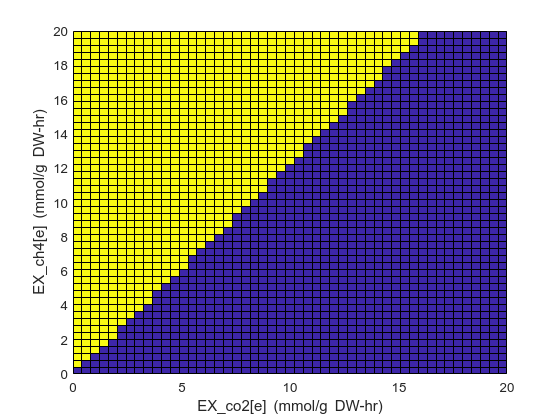

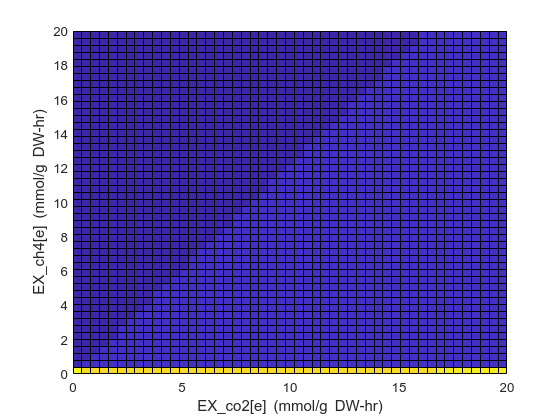

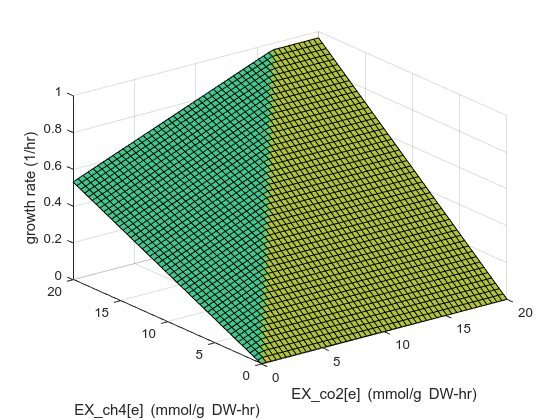

growthRates_overall =     0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000
    0.0108    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0196    0.0

shadowPrices1_overall =    -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.0266   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

shadowPrices2_overall =     0.5235    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.4839    0.5040    0.5040    0.5040    0.5040    0.5040    0.5040    0.5040    0.5040    0.5040
    0.0266    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0.0481    0

[growthRates_overall, shadowPrices1_overall, shadowPrices2_overall] = phenotypePhasePlane(model_methane, 'EX_co2[e]', 'EX_ch4[e]')

%% PhPP for Acetate in substrate with Methane: function of CO2 and CH4
model_methane = changeObjective(model_methane, 'EX_ac[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


generating PhPP
100%    [........................................]


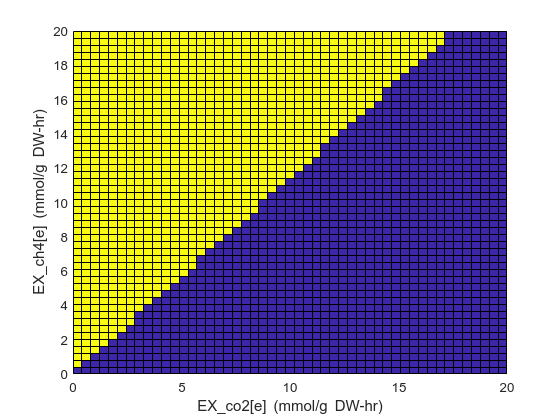

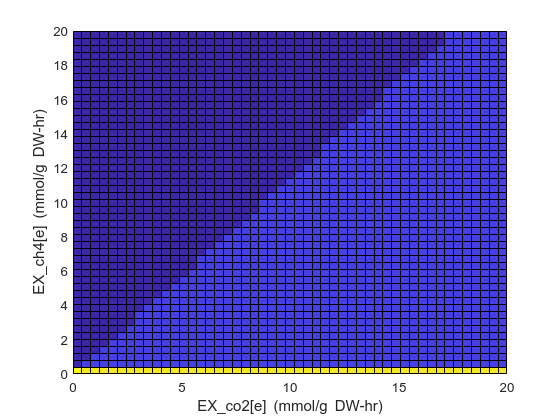

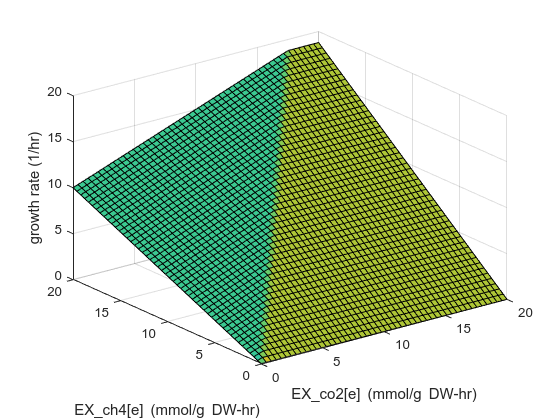

growthRates_ac =    -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.2041    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827    0.3827  

shadowPrices1_ac =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    0.5000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000

shadowPrices2_ac =     5.2500    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000    5.0000
    0.5000    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375    0.9375

[growthRates_ac, shadowPrices1_ac, shadowPrices2_ac] = phenotypePhasePlane(model_methane, 'EX_co2[e]', 'EX_ch4[e]')

%% PhPP for Methanol in substrate with Methane: function of CO2 and CH4
model_methane = changeObjective(model_methane, 'EX_meoh[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


generating PhPP
100%    [........................................]


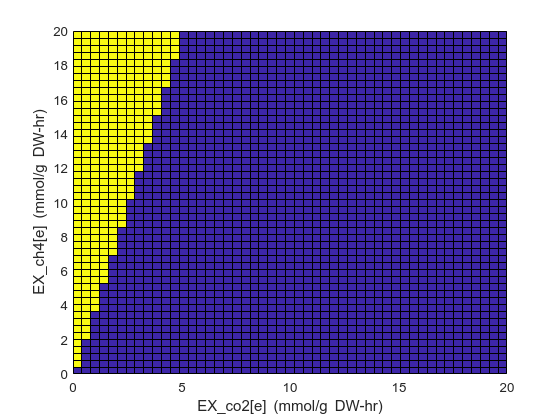

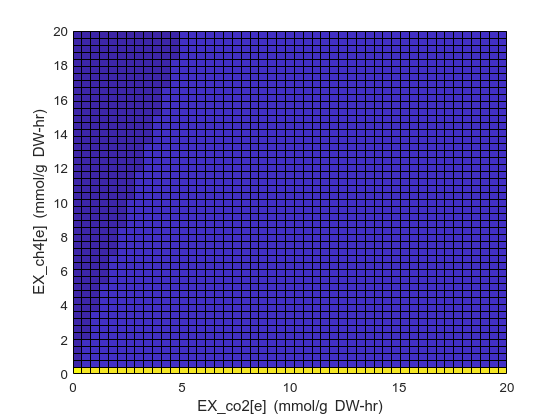

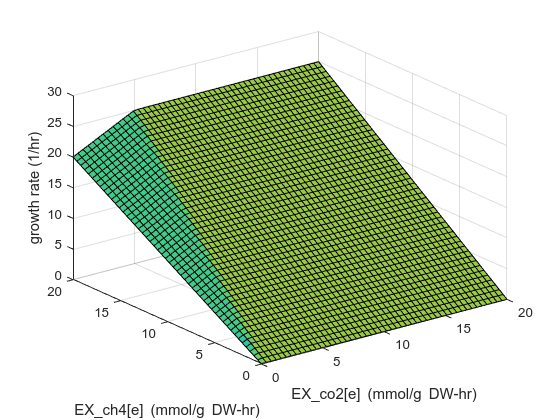

growthRates_meoh =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000
    0.4082    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102    0.5102

shadowPrices1_meoh =    -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.00

shadowPrices2_meoh =     7.0000    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667    6.6667
    1.0000    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.2500    1.25

[growthRates_meoh, shadowPrices1_meoh, shadowPrices2_meoh] = phenotypePhasePlane(model_methane, 'EX_co2[e]', 'EX_ch4[e]')

%% FVA for Biomass in native substrate and in substrate with methane
model_native = changeObjective(model_native, 'overall')

model_native = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_native.xlsx'


model_methane = changeObjective(model_methane, 'overall')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


[minflux_ns_overall, maxflux_ns_overall] = fluxVariability(model_native)

minflux_ns_overall = 	1.0e+03 *

    0.0000
    0.0000
   -0.0000
         0
         0
         0
         0
    0.0001
         0
    0.0000


maxflux_ns_overall = 	1.0e+03 *

    0.0000
    0.0000
   -0.0000
         0
         0
    0.0000
    0.0000
    0.0001
    0.0000
    0.0000


[minflux_m_overall, maxflux_m_overall] = fluxVariability(model_methane)

minflux_m_overall = 	1.0e+03 *

    0.0001
    0.0001
   -0.0001
         0
         0
         0
         0
    0.0004
         0
    0.0001


maxflux_m_overall = 	1.0e+03 *

    0.4095
    0.4095
   -0.0001
         0
         0
    0.4094
    0.4094
    0.0005
    0.2047
    0.2048


%% FVA for Acetate in native substrate and in substrate with methane
model_native = changeObjective(model_native, 'EX_ac[e]')

model_native = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_native.xlsx'


model_methane = changeObjective(model_methane, 'EX_ac[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


[minflux_ns_ac, maxflux_ns_ac] = fluxVariability(model_native)

minflux_ns_ac = 	1.0e+03 *

         0
         0
   -0.0000
         0
         0
         0
         0
         0
         0
         0


maxflux_ns_ac = 	1.0e+03 *

    0.0115
    0.0115
         0
         0
         0
    0.0115
    0.0115
    0.0024
    0.0058
    0.0058


[minflux_m_ac, maxflux_m_ac] = fluxVariability(model_methane)

minflux_m_ac = 	1.0e+03 *

         0
         0
    0.0000
         0
         0
         0
         0
    0.0000
         0
         0


maxflux_m_ac = 	1.0e+03 *

    0.4365
    0.4365
         0
         0
         0
    0.4365
    0.4365
    0.0000
    0.2183
    0.2183


%% FVA for Methanol in native substrate and in substrate with methane
model_native = changeObjective(model_native, 'EX_meoh[e]')

model_native = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_native.xlsx'


model_methane = changeObjective(model_methane, 'EX_meoh[e]')

model_methane = struct with fields:
              S: [718×845 double]
           mets: {718×1 cell}
              b: [718×1 double]
         csense: [718×1 char]
           rxns: {845×1 cell}
             lb: [845×1 double]
             ub: [845×1 double]
              c: [845×1 double]
      osenseStr: 'max'
          genes: {869×1 cell}
          rules: {845×1 cell}
      compNames: {2×1 cell}
          comps: {2×1 cell}
     metCharges: [718×1 double]
    metFormulas: {718×1 cell}
       metNames: {718×1 cell}
      metKEGGID: {718×1 cell}
        grRules: {845×1 cell}
     rxnGeneMat: [845×869 double]
       rxnNames: {845×1 cell}
     subSystems: {845×1 cell}
    description: 'iMAC868_GSM_methane.xlsx'


[minflux_ns_meoh, maxflux_ns_meoh] = fluxVariability(model_native)

minflux_ns_meoh = 	1.0e+03 *

         0
         0
   -0.0000
         0
         0
         0
         0
         0
         0
         0


maxflux_ns_meoh = 	1.0e+03 *

    0.0115
    0.0115
         0
         0
         0
    0.0115
    0.0115
    0.0024
    0.0058
    0.0058


[minflux_m_meoh, maxflux_m_meoh] = fluxVariability(model_methane)

minflux_m_meoh = 	1.0e+03 *

         0
         0
   -0.0000
         0
         0
         0
         0
         0
         0
         0


maxflux_m_meoh = 	1.0e+03 *

    0.4175
    0.4175
         0
         0
         0
    0.4175
    0.4175
    0.0000
    0.2088
    0.2088
